## Import fatigue data

clear all
data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

%data.Properties.VariableNames
%unique(data.ContactStressAmplitude_MPa_);
%groupcounts(data, "ContactStressAmplitude_MPa_"); 

## Parameter estimation using MLE

% a = location parameter (mu)
% b = scale parameter (sigma)
% fitting -cycles and negating the location gives the maximum Gumbel

stress_levels = unique(data.ContactStressAmplitude_MPa_);
num_stress_levels = numel(stress_levels);

% Arrays to store MLE estimates
a_estimates_MLE = zeros(num_stress_levels,1);
b_estimates_MLE = zeros(num_stress_levels,1);
B1_lives_Gumbel_MLE = zeros(num_stress_levels,1);

% Arrays to store plotting data
cdf_x_MLE = cell(num_stress_levels,1);
cdf_Gumbel_MLE = cell(num_stress_levels,1);
cdf_life_sorted_MLE = cell(num_stress_levels,1);

for i = 1:num_stress_levels
    current_stress = stress_levels(i);
    life_i = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == current_stress);
    %life_i = life_i(:);
    % MLE using MATLAB's evfit
    params_mle = mle(-life_i, "distribution","Extreme Value");
    % store minimum Gumbel paramaters
    mu_min = params_mle(1);
    sigma_min = params_mle(2);
    a_estimates_MLE(i) = -mu_min;
    b_estimates_MLE(i) = sigma_min;
    % B1 life: first percentile of the maximum Gumbel distribution
    pd_Gumbel = makedist('ExtremeValue', 'mu',mu_min, 'sigma', sigma_min)
    %B1_lives_Gumbel_MLE(i) = a_estimates_MLE(i) ...
        %- b_estimates_MLE(i)*log(-log(0.01));
    B1_lives_Gumbel_MLE(i) = -icdf(pd_Gumbel, 0.99);

    % Calculate fitted CDF for plotting
    life_i_sorted = sort(life_i);
    life_i_lin = logspace(log10(min(life_i_sorted)),log10(max(life_i_sorted)), 200);

    cdf_fit = exp(-exp(-(life_i_lin - a_estimates_MLE(i))./ b_estimates_MLE(i)));

    cdf_x_MLE{i} = life_i_lin;
    cdf_Gumbel_MLE{i} = cdf_fit;
    cdf_life_sorted_MLE{i} = life_i_sorted;
end

pd_Gumbel =   ExtremeValueDistribution

  Extreme Value distribution
       mu = -2.0764e+08
    sigma = 2.11542e+08


pd_Gumbel =   ExtremeValueDistribution

  Extreme Value distribution
       mu = -7.89302e+07
    sigma =  7.96151e+07


pd_Gumbel =   ExtremeValueDistribution

  Extreme Value distribution
       mu = -3.85184e+07
    sigma =  3.41885e+07


pd_Gumbel =   ExtremeValueDistribution

  Extreme Value distribution
       mu = -2.12791e+07
    sigma =   3.0601e+07



% Display MLE results
results_Gumbel_MLE = table(stress_levels, a_estimates_MLE, b_estimates_MLE, B1_lives_Gumbel_MLE, 'VariableNames', {'Stress_MPa','Location_MLE','Scale_MLE','B1_MLE'})

results_Gumbel_MLE = 4×4 table
    Stress_MPa    Location_MLE    Scale_MLE       B1_MLE   
    __________    ____________    __________    ___________

       4900        2.0764e+08     2.1154e+08    -1.1542e+08
       5500         7.893e+07     7.9615e+07    -4.2656e+07
       6100        3.8518e+07     3.4188e+07    -1.3693e+07
       6700        2.1279e+07     3.0601e+07    -2.5454e+07


## PPLR 

current_stress = 4900

dF_tail =    -0.0422
    0.0096
    0.0481


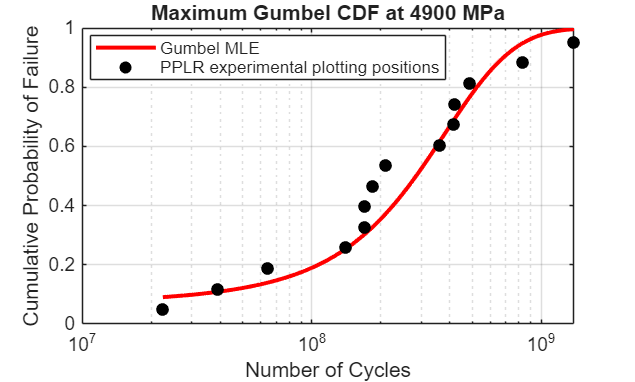

current_stress = 5500

dF_tail =    -0.0409
    0.0108
    0.0486


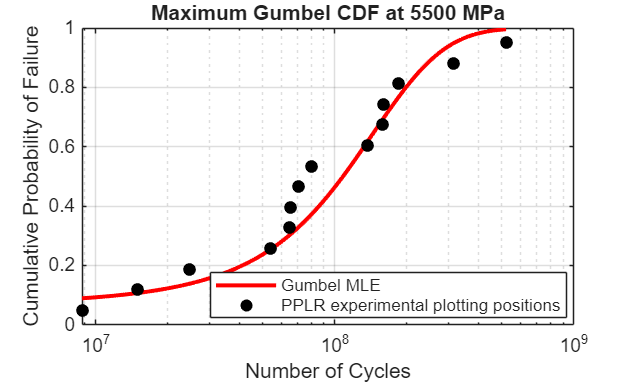

current_stress = 6100

dF_tail =    -0.0258
    0.0219
    0.0539


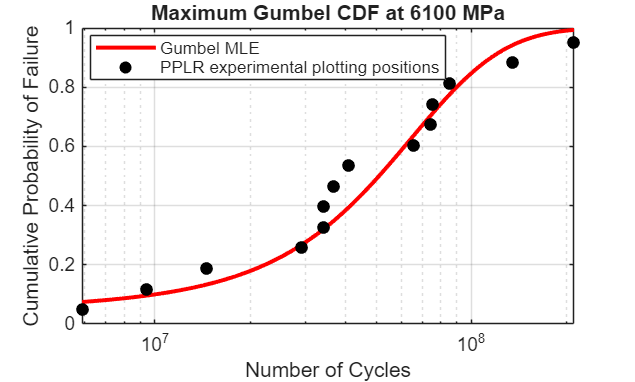

current_stress = 6700

dF_tail =    -0.1009
   -0.0433
    0.0180


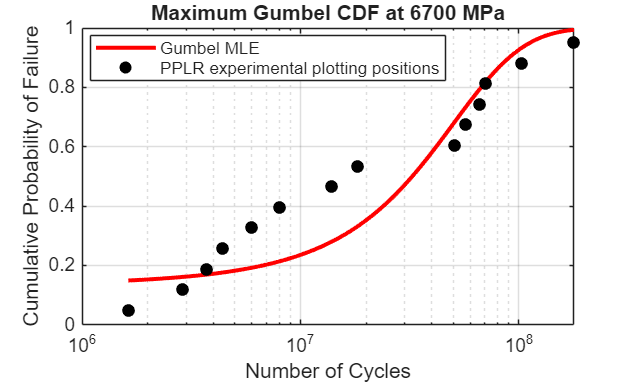

% PPLR 
% Median rank plotting positions
% F_i = (i - 0.3)/(n + 0.4)
r_max_array = zeros(num_stress_levels, 1);
max_rank_eq = zeros(num_stress_levels, 2);
a_estimates_PPLR = zeros(num_stress_levels, 1);
b_estimates_PPLR = zeros(num_stress_levels, 1);
rank_equation = strings(num_stress_levels, 1);
B1_lives_PPLR = zeros(num_stress_levels, 1);

% anderson-darling info
p = zeros(num_stress_levels, 1);
ad_test = zeros(num_stress_levels, 1);
ad_h = zeros(num_stress_levels, 1);
ad_cv = zeros(num_stress_levels, 1);

% stores tail-fit results at the 3 lowest fatigue lives
tail_fit_lives_G = cell(num_stress_levels, 1);
tail_fit_dF_G = cell(num_stress_levels, 1);
tail_fit_abs_dF_G = cell(num_stress_levels, 1);
tail_fit_F_empirical_G = cell(num_stress_levels,1);
tail_fit_dF_PPLR_G = cell(num_stress_levels, 1);
tail_fit_abs_dF_PPLR_G = cell(num_stress_levels, 1);

% cell arrays to store linearized plotting data
probability_X = cell(num_stress_levels, 1);
probability_Y = cell(num_stress_levels, 1);
probability_Y_fit = cell(num_stress_levels, 1);

for j = 1:num_stress_levels
    %j
    current_stress = stress_levels(j)
    life_j = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == stress_levels(j)); % extract the number of cycles for the current stress level
    life_j = life_j(:);
    num_observations_j = numel(life_j);
    life_j_sorted = sort(life_j); % sorts the lives in ascending order
    X_j = life_j_sorted; % calculates the X values for the linearised Gumbel form
    observation_ranks = (1:num_observations_j)';

    % Median rank plotting positions
    F = (observation_ranks - 0.3) ./ (num_observations_j + 0.4);
    % Linearised Gumbel probabilities
    Y_j = log(-log(F));
    % Use all observations
    X_fit = X_j;
    F_mxg = F;

    % Calculate correlation coefficient
    r_matrix = corrcoef(X_fit, Y_j);
    max_r = r_matrix(1, 2);

    r_max_array(j) = max_r;
    rank_equation(j) = "Median Rank";

    % linear regression
    fitted_line = polyfit(X_fit, Y_j, 1);
    reg_slope = fitted_line(1);
    reg_intercept = fitted_line(2);
    b_est_PPLR = -1 / reg_slope;
    a_est_PPLR = reg_intercept * b_est_PPLR;

    % Store data for combined linearized plotting
    probability_X{j} = X_fit;
    probability_Y{j} = Y_j;
    probability_Y_fit{j} = polyval(fitted_line, X_fit);
    % store the parameter estimates for PPLR
    a_estimates_PPLR(j) = a_est_PPLR;
    b_estimates_PPLR(j) = b_est_PPLR;

    % Estimate the B1 life from the fitted Gumbel distribution - PPLR
    B1_lives_PPLR(j) = a_est_PPLR - b_est_PPLR * (log(-log(0.01)));
    % Plot the MLE CDF and use the probability plotting from above for experimental data
    life_j_lin = cdf_x_MLE{j};
    cdf_G_mle = cdf_Gumbel_MLE{j};

    % Tail-fit check at the 3 lowest observed fatigue lives
    N_tail = life_j_sorted(1:3);
    F_empirical_tail = F(1:3);
    tail_fit_F_empirical_G{j} = F_empirical_tail;
    % Predicted CDF using Gumbel maximum MLE parameters
    F_predicted_tail = exp(-exp(-(N_tail - a_estimates_MLE(j)) ./ b_estimates_MLE(j)));

    % Signed and absolute CDF differences for MLE 
    dF_tail = F_empirical_tail - F_predicted_tail
    abs_dF_tail = abs(dF_tail);
    tail_fit_lives_G{j} = N_tail;
    tail_fit_dF_G{j} = dF_tail;
    tail_fit_abs_dF_G{j} = abs_dF_tail;

    % Tail-fit check using maximum Gumbel PPLR parameters
    F_predicted_tail_PPLR = exp(-exp(-(N_tail - a_estimates_PPLR(j)) ./ b_estimates_PPLR(j)));

    dF_tail_PPLR = F_empirical_tail - F_predicted_tail_PPLR;
    abs_dF_tail_PPLR = abs(dF_tail_PPLR);

    % Store PPLR tail-fit differences
    tail_fit_dF_PPLR_G{j} = dF_tail_PPLR;
    tail_fit_abs_dF_PPLR_G{j} = abs_dF_tail_PPLR;

    % Plot 1: MLE CDF with the selected PPLR experimental plotting positions
    figure
    plot(life_j_lin, cdf_G_mle, 'Color', 'r', ...
        'LineWidth', 2, 'LineStyle', '-');
    hold on
    scatter(X_fit, F_mxg, 40, 'k', 'filled');
    xlabel('Number of Cycles');
    ylabel('Cumulative Probability of Failure');
    title(sprintf('Maximum Gumbel CDF at %g MPa', current_stress));
    legend('Gumbel MLE', 'PPLR experimental plotting positions', ...
        'Location', 'best');
    set(gca, 'XScale', 'log');
    grid on
    hold off


    % conduct an anderson-darling GoF test
    clear adtest % adtest got initialised as a variable for some reason, this clears it to avoid errors
    [h, p_value, test_stat, cv] = adtest(-life_j,"Distribution","ev"); % for unspecified parameters for the max extreme value distribution, returns h (rejects or accepts the null hypothesis, p-value, the test statistic ad the critical value
    p(j) = p_value;
    ad_test(j) = test_stat;
    ad_h(j) = h;
    ad_cv(j) = cv;
end


a_estimates_PPLR

a_estimates_PPLR = 1.0e+08 *

    1.6680
    0.6396
    0.3369
    0.1660


b_estimates_PPLR

b_estimates_PPLR = 1.0e+08 *

    3.4326
    1.2814
    0.5068
    0.4718


r_max_array

r_max_array =    -0.9415
   -0.9432
   -0.9590
   -0.9474


B1_lives_PPLR

B1_lives_PPLR = 1.0e+08 *

   -3.5742
   -1.3174
   -0.4370
   -0.5544



results_Gumbel_PPLR = table(stress_levels, a_estimates_MLE, ...
    b_estimates_MLE, B1_lives_Gumbel_MLE, a_estimates_PPLR, ...
    b_estimates_PPLR, B1_lives_PPLR, r_max_array, rank_equation, ...
    'VariableNames', {'Stress_MPa','Location_MLE','Scale_MLE', ...
    'B1_MLE','Location_PPLR','Scale_PPLR','B1_PPLR', ...
    'Correlation_r','PlottingPosition'});

## Check the % difference between MLE and PPLR estimates 

percentage_diff_location = (abs(a_estimates_MLE -a_estimates_PPLR) ./ abs(a_estimates_MLE)) * 100;
percentage_diff_scale = (abs(b_estimates_MLE - b_estimates_PPLR) ./ abs(b_estimates_MLE)) * 100;
%percentage_diff_B1_life =((B1_lives_PPLR - B1_lives_Gumbel_MLE) ./abs(B1_lives_Gumbel_MLE)) * 100;

Gumbel_percentage_differences = table( stress_levels,percentage_diff_location,percentage_diff_scale, ...
    'VariableNames', {'Stress_MPa','Location_Percent_Difference', 'Scale_Percent_Difference'});
Gumbel_percentage_differences

Gumbel_percentage_differences = 4×3 table
    Stress_MPa    Location_Percent_Difference    Scale_Percent_Difference
    __________    ___________________________    ________________________

       4900                 19.669                        62.265         
       5500                  18.97                        60.955         
       6100                 12.546                        48.223         
       6700                  21.97                        54.169         


## PPLR plots in one panel 

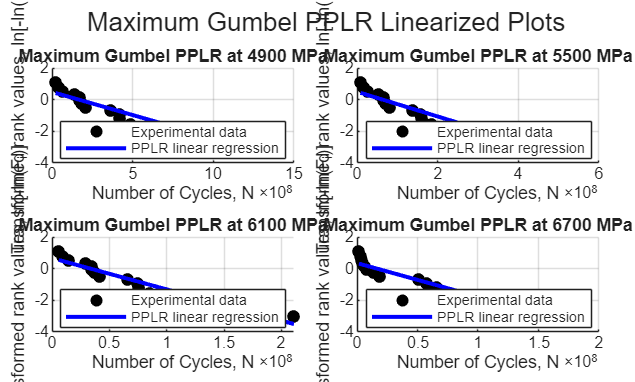

figure('Name','Gumbel PPLR Linearized Plots');
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

for j = 1:num_stress_levels
    nexttile
    scatter(probability_X{j}, probability_Y{j}, 40, 'k', 'filled');
    hold on;
    plot(probability_X{j}, probability_Y_fit{j}, 'b-', 'LineWidth', 2);
    xlabel('Number of Cycles, N');
    ylabel('Transformed rank values, ln[-ln(F_i)]');
    title(sprintf('Maximum Gumbel PPLR at %g MPa', stress_levels(j)));
    legend('Experimental data','PPLR linear regression','Location','best');
    grid on;
    hold off;
end
sgtitle('Maximum Gumbel PPLR Linearized Plots');

## Export results 

save('results_Gumbel_Steel.mat', ...
    'stress_levels', ...
    'a_estimates_MLE', ...
    'b_estimates_MLE', ...
    'B1_lives_Gumbel_MLE', ...
    'a_estimates_PPLR', ...
    'b_estimates_PPLR', ...
    'B1_lives_PPLR', ...
    'r_max_array', ...
    'rank_equation', ...
    'ad_h', ...
    'p', ...
    'ad_test', ...
    'ad_cv', ...
    'cdf_x_MLE', ...
    'cdf_Gumbel_MLE', ...
    'cdf_life_sorted_MLE', ...
    'results_Gumbel_MLE', ...
    'results_Gumbel_PPLR', ...
    'tail_fit_lives_G', ...
    'tail_fit_F_empirical_G', ...
    'tail_fit_dF_G', ...
    'tail_fit_dF_PPLR_G', ...
    'tail_fit_abs_dF_PPLR_G', ...
    'tail_fit_abs_dF_G')